clc
clear 
close all


## Load results

filename_calm = '100MW wind farm Calm Weather Results.xlsx';
sheet_names_ca = {'T_TOT', 'COST_TOT', 'T_POS_TOT', 'T_LOAD_TOT', 'T_CON_TOT', 'T_TOW_TOT', 'T_NAC_TOT', 'T_BLADE_TOT', 'T_COM_TOT', 'T_TRANS_TOT'};


% Initialize cell arrays to store data and headers
data_ca = cell(length(sheet_names_ca), 1);
headers_ca = cell(length(sheet_names_ca), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names_ca)
    [data_ca{i}, headers_ca{i}] = xlsread(filename_calm , sheet_names_ca{i});
end

T_TOT_CALM = data_ca{1};
T_TOT_CALM = T_TOT_CALM(1,1:6);
COST_TOT_CALM = data_ca{2};
COST_TOT_CALM = COST_TOT_CALM(1,1:6);
T_POS_TOT_CALM = data_ca{3};
T_LOAD_TOT_CALM = data_ca{4};
T_CON_TOT_CALM = data_ca{5};
T_TOW_TOT_CALM = data_ca{6};
T_NAC_TOT_CALM = data_ca{7};
T_BLADE_TOT_CALM = data_ca{8};
T_COM_TOT_CALM = data_ca{9};
T_TRANS_TOT_CALM = data_ca{10};

% Define the Excel file name and sheet names
filename_weather = '100MW wind farm Results.xlsx';
sheet_names = {'T_TOT', 'COST_TOT', 'WAIT_TOT', 'Waiting_position', 'Waiting_transfer',...
                'Waiting_connect', 'Waiting_position', 'Waiting_tower', 'Waiting_nacelle',...
                'Waiting_position', 'Waiting_blade', 'Waiting_commission', 'Waiting_transit',...
                'Waiting_wave', 'Waiting_wind', 'Waiting_tide','Waiting_WindWave'};

% Initialize cell arrays to store data and headers
data = cell(length(sheet_names), 1);
headers = cell(length(sheet_names), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names)
    [data{i}, headers{i}] = xlsread(filename_weather, sheet_names{i});
end

T_TOT = data{1};
COST_TOT = data{2};
WAIT_TOT = data{3};
Waiting_position = data{4};
Waiting_transfer = data{5};
Waiting_connect = data{6};
Waiting_tower = data{8};
Waiting_nacelle = data{9};
Waiting_blade = data{11};
Waiting_commission = data{12};
Waiting_transit = data{13};
Waiting_wave = data{14};
Waiting_wind = data{15};
Waiting_tide = data{16};
Waiting_windwave = data{17};

std_T_TOT = std(T_TOT(1:10,:), 1);
std_COST_TOT = std(COST_TOT(1:10,:), 1);
std_WAIT_TOT = std(WAIT_TOT(1:10,:), 1);
std_Ops14 = [std(Waiting_transit(1:10,1),1) std(Waiting_transit(1:10,4),1);std(Waiting_position(1:10,1),1) std(Waiting_position(1:10,4),1);std(Waiting_transfer(1:10,1),1) std(Waiting_transfer(1:10,4),1);std(Waiting_connect(1:10,1),1) std(Waiting_connect(1:10,4),1);std(Waiting_tower(1:10,1),1) std(Waiting_tower(1:10,4),1);std(Waiting_nacelle(1:10,1),1) std(Waiting_nacelle(1:10,4),1);std(Waiting_blade(1:10,1),1) std(Waiting_blade(1:10,4),1);std(Waiting_commission(1:10,1),1) std(Waiting_commission(1:10,4),1)]';

filename_month = '100MW wind farm Month Check.xlsx';

sheet_names_mo = {'T_TOT', 'COST_TOT', 'WAIT_TOT', ...
                'Waiting_wave', 'Waiting_wind', 'Waiting_tide','Waiting_WindWave'};
% Initialize cell arrays to store data and headers
data_mo = cell(length(sheet_names_mo), 1);
headers_mo  = cell(length(sheet_names_mo), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names_mo)
    [data_mo{i}, headers_mo{i}] = xlsread(filename_month, sheet_names_mo{i});
end

T_TOT_mo  = data_mo{1};
COST_TOT_mo  = data_mo{2};
WAIT_TOT_mo  = data_mo{3};
Waiting_wave_mo = data_mo{4};
Waiting_wind_mo = data_mo{5};
Waiting_tide_mo = data_mo{6};
Waiting_windwave_mo = data_mo{7};


% Define the Excel file name and sheet names
filename_weather_lo = '100MW wind farm Results Low.xlsx';
sheet_names = {'T_TOT', 'COST_TOT', 'WAIT_TOT', 'Waiting_position', 'Waiting_transfer',...
                'Waiting_connect', 'Waiting_position', 'Waiting_tower', 'Waiting_nacelle',...
                'Waiting_position', 'Waiting_blade', 'Waiting_commission', 'Waiting_transit',...
                'Waiting_wave', 'Waiting_wind', 'Waiting_tide','Waiting_WindWave'};

% Initialize cell arrays to store data and headers
data = cell(length(sheet_names), 1);
headers = cell(length(sheet_names), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names)
    [data{i}, headers{i}] = xlsread(filename_weather_lo, sheet_names{i});
end

T_TOT_lo = data{1};
COST_TOT_lo = data{2};
WAIT_TOT_lo = data{3};
Waiting_position_lo = data{4};
Waiting_transfer_lo = data{5};
Waiting_connect_lo = data{6};
Waiting_tower_lo = data{8};
Waiting_nacelle_lo = data{9};
Waiting_blade_lo = data{11};
Waiting_commission_lo = data{12};
Waiting_transit_lo = data{13};
Waiting_wave_lo = data{14};
Waiting_wind_lo = data{15};
Waiting_tide_lo = data{16};
Waiting_windwave_lo = data{17};

std_T_TOT_lo = std(T_TOT_lo(1:10,:), 1);
std_COST_TOT_lo = std(COST_TOT_lo(1:10,:), 1);
std_WAIT_TOT_lo = std(WAIT_TOT_lo(1:10,:), 1);
std_Ops14_lo = [std(Waiting_transit_lo(1:10,1),1) std(Waiting_transit_lo(1:10,4),1);std(Waiting_position(1:10,1),1) std(Waiting_position_lo(1:10,4),1);std(Waiting_transfer_lo(1:10,1),1) std(Waiting_transfer_lo(1:10,4),1);std(Waiting_connect_lo(1:10,1),1) std(Waiting_connect_lo(1:10,4),1);std(Waiting_tower_lo(1:10,1),1) std(Waiting_tower_lo(1:10,4),1);std(Waiting_nacelle_lo(1:10,1),1) std(Waiting_nacelle_lo(1:10,4),1);std(Waiting_blade_lo(1:10,1),1) std(Waiting_blade_lo(1:10,4),1);std(Waiting_commission_lo(1:10,1),1) std(Waiting_commission_lo(1:10,4),1)]';


% Define the Excel file name and sheet names
filename_weather_lo = '100MW wind farm Results High.xlsx';
sheet_names = {'T_TOT', 'COST_TOT', 'WAIT_TOT', 'Waiting_position', 'Waiting_transfer',...
                'Waiting_connect', 'Waiting_position', 'Waiting_tower', 'Waiting_nacelle',...
                'Waiting_position', 'Waiting_blade', 'Waiting_commission', 'Waiting_transit',...
                'Waiting_wave', 'Waiting_wind', 'Waiting_tide'};

% Initialize cell arrays to store data and headers
data = cell(length(sheet_names), 1);
headers = cell(length(sheet_names), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names)
    [data{i}, headers{i}] = xlsread(filename_weather_lo, sheet_names{i});
end

T_TOT_hi = data{1};
COST_TOT_hi = data{2};
WAIT_TOT_hi = data{3};
Waiting_position_hi = data{4};
Waiting_transfer_hi = data{5};
Waiting_connect_hi = data{6};
Waiting_tower_hi = data{8};
Waiting_nacelle_hi = data{9};
Waiting_blade_hi = data{11};
Waiting_commission_hi = data{12};
Waiting_transit_hi = data{13};
Waiting_wave_hi = data{14};
Waiting_wind_hi = data{15};
Waiting_tide_hi = data{16};

std_T_TOT_hi = std(T_TOT_hi(1:10,:), 1);
std_COST_TOT_hi = std(COST_TOT_hi(1:10,:), 1);
std_WAIT_TOT_hi = std(WAIT_TOT_hi(1:10,:), 1);
std_Ops14_hi = [std(Waiting_transit_hi(1:10,1),1) std(Waiting_transit_hi(1:10,4),1);std(Waiting_position(1:10,1),1) std(Waiting_position_hi(1:10,4),1);std(Waiting_transfer_hi(1:10,1),1) std(Waiting_transfer_hi(1:10,4),1);std(Waiting_connect_hi(1:10,1),1) std(Waiting_connect_hi(1:10,4),1);std(Waiting_tower_hi(1:10,1),1) std(Waiting_tower_hi(1:10,4),1);std(Waiting_nacelle_hi(1:10,1),1) std(Waiting_nacelle_hi(1:10,4),1);std(Waiting_blade_hi(1:10,1),1) std(Waiting_blade_hi(1:10,4),1);std(Waiting_commission_hi(1:10,1),1) std(Waiting_commission_hi(1:10,4),1)]';

% Define the Excel file name and sheet names
filename_weather = '200MW wind farm Results.xlsx';
sheet_names = {'T_TOT', 'COST_TOT', 'WAIT_TOT', 'Waiting_position', 'Waiting_transfer',...
                'Waiting_connect', 'Waiting_position', 'Waiting_tower', 'Waiting_nacelle',...
                'Waiting_position', 'Waiting_blade', 'Waiting_commission', 'Waiting_transit',...
                'Waiting_wave', 'Waiting_wind', 'Waiting_tide','Waiting_WindWave'};

% Initialize cell arrays to store data and headers
data = cell(length(sheet_names), 1);
headers = cell(length(sheet_names), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names)
    [data{i}, headers{i}] = xlsread(filename_weather, sheet_names{i});
end

T_TOT_200 = data{1};
COST_TOT_200 = data{2};
WAIT_TOT_200 = data{3};
Waiting_position_200 = data{4};
Waiting_transfer_200 = data{5};
Waiting_connect_200 = data{6};
Waiting_tower_200 = data{8};
Waiting_nacelle_200 = data{9};
Waiting_blade_200 = data{11};
Waiting_commission_200 = data{12};
Waiting_transit_200 = data{13};
Waiting_wave_200 = data{14};
Waiting_wind_200 = data{15};
Waiting_tide_200 = data{16};
Waiting_windwave_200 = data{17};

std_T_TOT_200 = std(T_TOT_200(1:10,:), 1);
std_COST_TOT_200 = std(COST_TOT_200(1:10,:), 1);
std_WAIT_TOT_200 = std(WAIT_TOT_200(1:10,:), 1);

% Define the Excel file name and sheet names
filename_weather = '500MW wind farm Results.xlsx';
sheet_names = {'T_TOT', 'COST_TOT', 'WAIT_TOT', 'Waiting_position', 'Waiting_transfer',...
                'Waiting_connect', 'Waiting_position', 'Waiting_tower', 'Waiting_nacelle',...
                'Waiting_position', 'Waiting_blade', 'Waiting_commission', 'Waiting_transit',...
                'Waiting_wave', 'Waiting_wind', 'Waiting_tide','Waiting_WindWave'};

% Initialize cell arrays to store data and headers
data = cell(length(sheet_names), 1);
headers = cell(length(sheet_names), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names)
    [data{i}, headers{i}] = xlsread(filename_weather, sheet_names{i});
end

T_TOT_500 = data{1};
COST_TOT_500 = data{2};
WAIT_TOT_500 = data{3};
Waiting_position_500 = data{4};
Waiting_transfer_500 = data{5};
Waiting_connect_500 = data{6};
Waiting_tower_500 = data{8};
Waiting_nacelle_500 = data{9};
Waiting_blade_500 = data{11};
Waiting_commission_500 = data{12};
Waiting_transit_500 = data{13};
Waiting_wave_500 = data{14};
Waiting_wind_500 = data{15};
Waiting_tide_500 = data{16};
Waiting_windwave_500 = data{17};

std_T_TOT_500 = std(T_TOT_500(1:10,:), 1);
std_COST_TOT_500 = std(COST_TOT_500(1:10,:), 1);
std_WAIT_TOT_500 = std(WAIT_TOT_500(1:10,:), 1);
%std_Ops14 = [std(Waiting_transit(1:10,1),1) std(Waiting_transit(1:10,4),1);std(Waiting_position(1:10,1),1) std(Waiting_position(1:10,4),1);std(Waiting_transfer(1:10,1),1) std(Waiting_transfer(1:10,4),1);std(Waiting_connect(1:10,1),1) std(Waiting_connect(1:10,4),1);std(Waiting_tower(1:10,1),1) std(Waiting_tower(1:10,4),1);std(Waiting_nacelle(1:10,1),1) std(Waiting_nacelle(1:10,4),1);std(Waiting_blade(1:10,1),1) std(Waiting_blade(1:10,4),1);std(Waiting_commission(1:10,1),1) std(Waiting_commission(1:10,4),1)]';


filename_calm = '200MW wind farm Calm Weather Results.xlsx';
sheet_names_ca = {'T_TOT', 'COST_TOT', 'T_POS_TOT', 'T_LOAD_TOT', 'T_CON_TOT', 'T_TOW_TOT', 'T_NAC_TOT', 'T_BLADE_TOT', 'T_COM_TOT', 'T_TRANS_TOT'};


% Initialize cell arrays to store data and headers
data_ca = cell(length(sheet_names_ca), 1);
headers_ca = cell(length(sheet_names_ca), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names_ca)
    [data_ca{i}, headers_ca{i}] = xlsread(filename_calm , sheet_names_ca{i});
end

T_TOT_CALM_200 = data_ca{1};
T_TOT_CALM_200 = T_TOT_CALM_200(1,1:6);
COST_TOT_CALM_200 = data_ca{2};
COST_TOT_CALM_200 = COST_TOT_CALM_200(1,1:6);
T_POS_TOT_CALM_200 = data_ca{3};
T_LOAD_TOT_CALM_200 = data_ca{4};
T_CON_TOT_CALM_200 = data_ca{5};
T_TOW_TOT_CALM_200 = data_ca{6};
T_NAC_TOT_CALM_200 = data_ca{7};
T_BLADE_TOT_CALM_200 = data_ca{8};
T_COM_TOT_CALM_200 = data_ca{9};
T_TRANS_TOT_CALM_200 = data_ca{10};

filename_calm = '500MW wind farm Calm Weather Results.xlsx';
sheet_names_ca = {'T_TOT', 'COST_TOT', 'T_POS_TOT', 'T_LOAD_TOT', 'T_CON_TOT', 'T_TOW_TOT', 'T_NAC_TOT', 'T_BLADE_TOT', 'T_COM_TOT', 'T_TRANS_TOT'};


% Initialize cell arrays to store data and headers
data_ca = cell(length(sheet_names_ca), 1);
headers_ca = cell(length(sheet_names_ca), 1);

% Read data from each sheet using a loop
for i = 1:length(sheet_names_ca)
    [data_ca{i}, headers_ca{i}] = xlsread(filename_calm , sheet_names_ca{i});
end

T_TOT_CALM_500 = data_ca{1};
T_TOT_CALM_500 = T_TOT_CALM_500(1,1:6);
COST_TOT_CALM_500 = data_ca{2};
COST_TOT_CALM_500 = COST_TOT_CALM_500(1,1:6);
T_POS_TOT_CALM_500 = data_ca{3};
T_LOAD_TOT_CALM_500 = data_ca{4};
T_CON_TOT_CALM_500 = data_ca{5};
T_TOW_TOT_CALM_500 = data_ca{6};
T_NAC_TOT_CALM_500 = data_ca{7};
T_BLADE_TOT_CALM_500 = data_ca{8};
T_COM_TOT_CALM_500 = data_ca{9};
T_TRANS_TOT_CALM_500 = data_ca{10};

## Calm weather plots

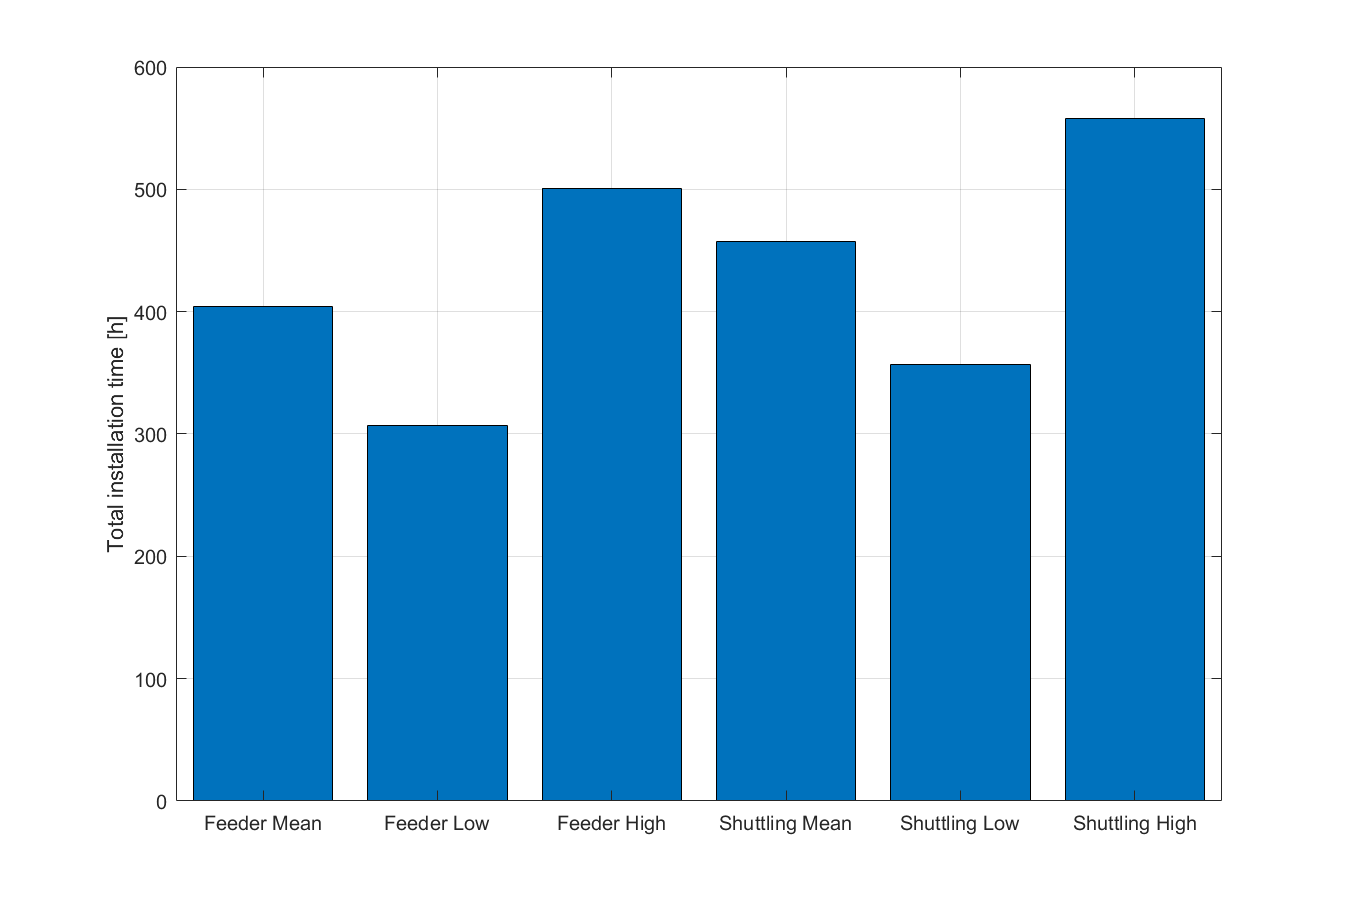

x=categorical({'Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High'});
x = reordercats(x,{'Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High'});
T_TOT_bars=[T_TOT_CALM]';
f71=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,T_TOT_bars,'stacked'), hold on
ylabel('Total installation time [h]')
grid on


exportgraphics(f71,'TotInstTimeCalm.pdf')

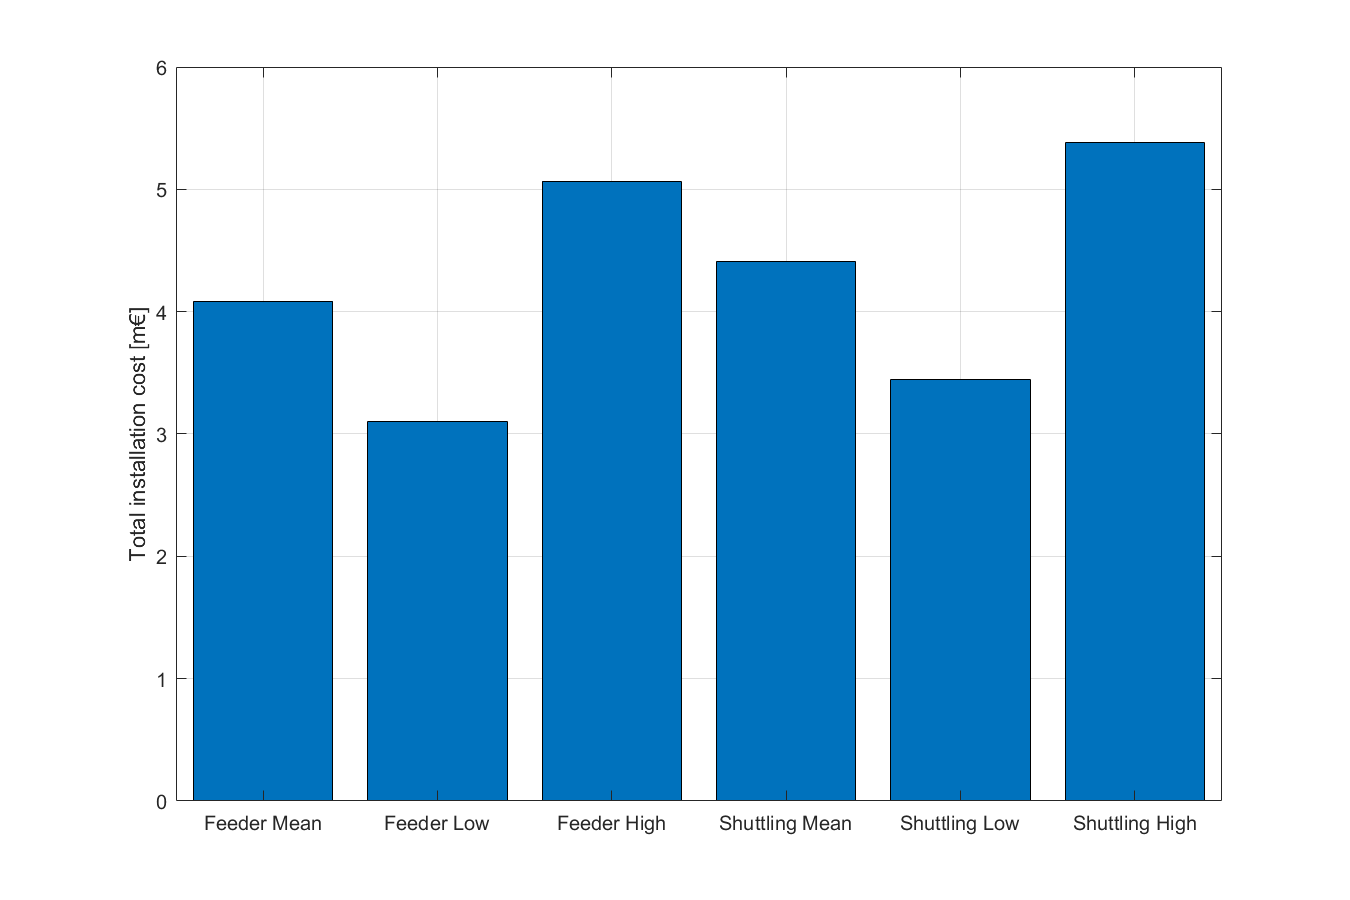



COST_TOT_bars=[COST_TOT_CALM/1000]';
f72=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,COST_TOT_bars,'stacked'), hold on
ylabel('Total installation cost [m€]')
grid on

exportgraphics(f72,'TotInstCostCalm.pdf')

## Scenario plots

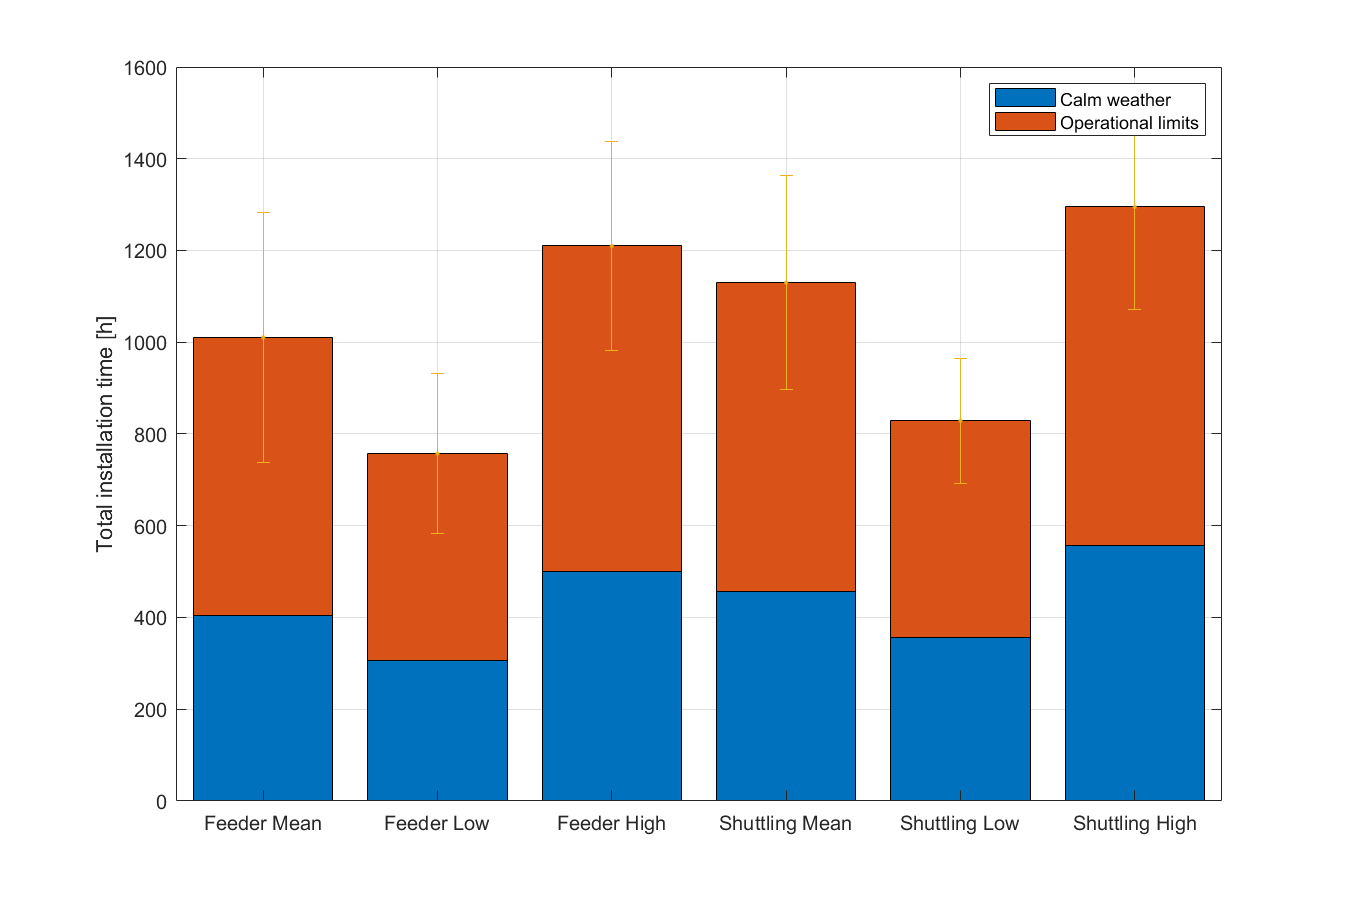


x=categorical({'Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High'});
x = reordercats(x,{'Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High'});
T_TOT_bars=[T_TOT_CALM; T_TOT(11,:)-T_TOT_CALM]';
f1=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,T_TOT_bars,'stacked'), hold on
errorbar(T_TOT(11,:),std_T_TOT ,'.')
ylabel('Total installation time [h]')
grid on
legend('Calm weather','Operational limits')

exportgraphics(f1,'TotInstTime.pdf')

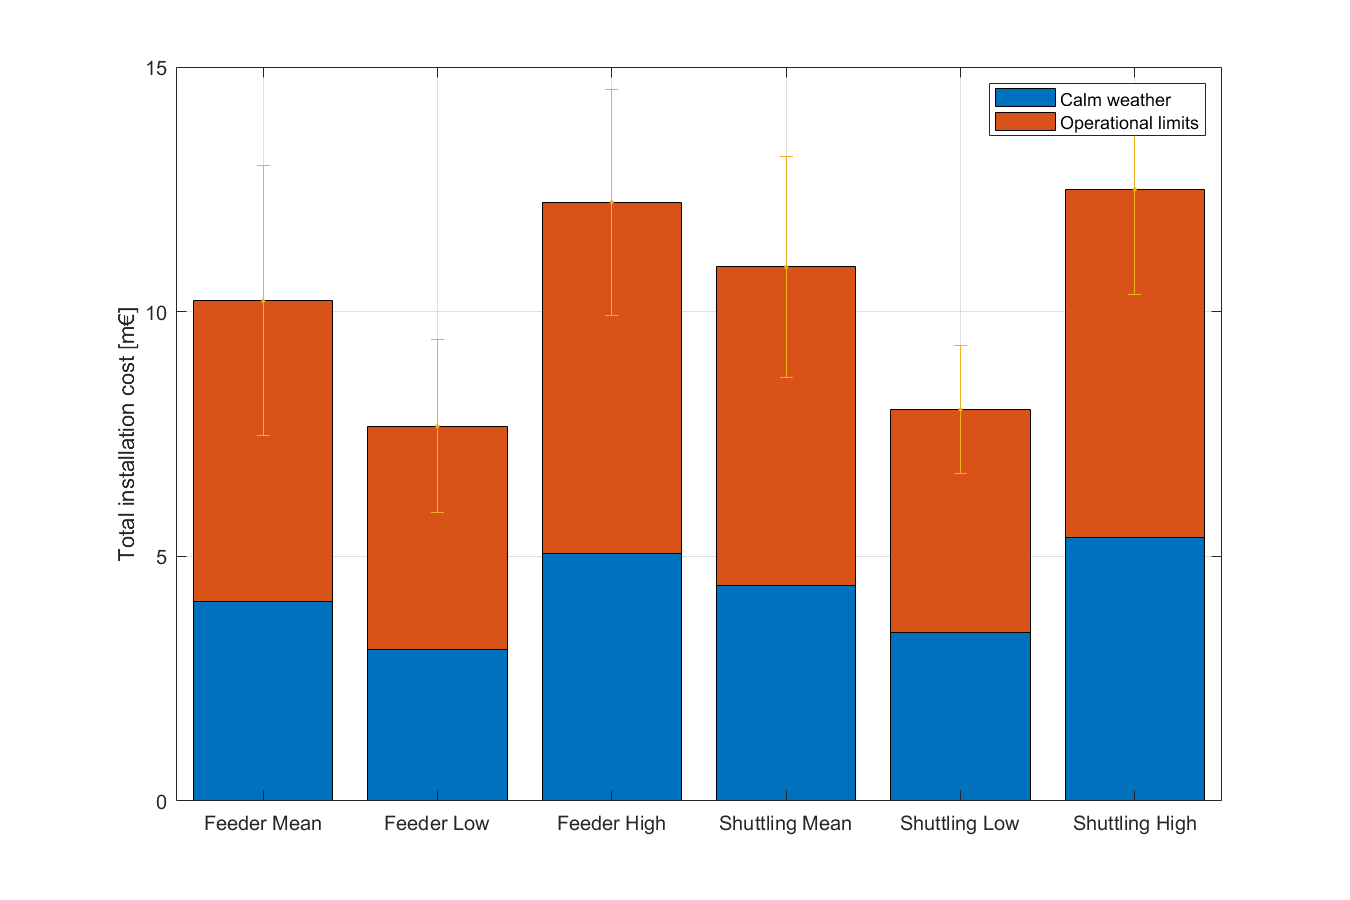



COST_TOT_bars=[COST_TOT_CALM/1000; (COST_TOT(11,:)-COST_TOT_CALM)/1000]';
f2=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,COST_TOT_bars,'stacked'), hold on
errorbar(COST_TOT(11,:)/1000,std_COST_TOT/1000 ,'.')
ylabel('Total installation cost [m€]')
grid on
legend('Calm weather','Operational limits')
exportgraphics(f2,'TotInstCost.pdf')

## Ratio plots

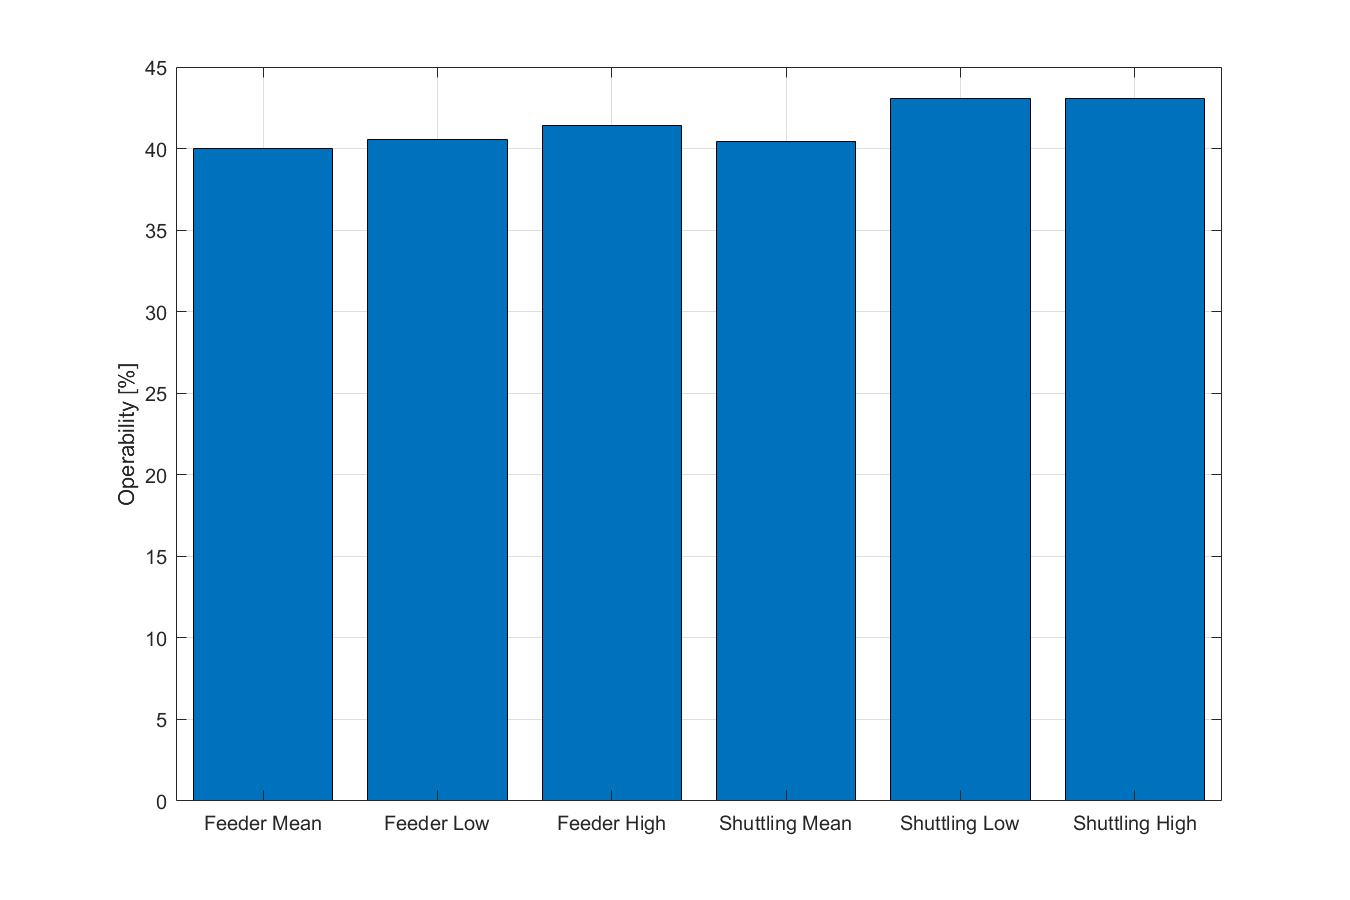

Ratios=[((T_TOT_CALM./T_TOT(11,:)))*100]';
f3=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,Ratios), hold on
ylabel('Operability [%]')
grid on
exportgraphics(f3,'Operability.pdf')

## Waiting plots

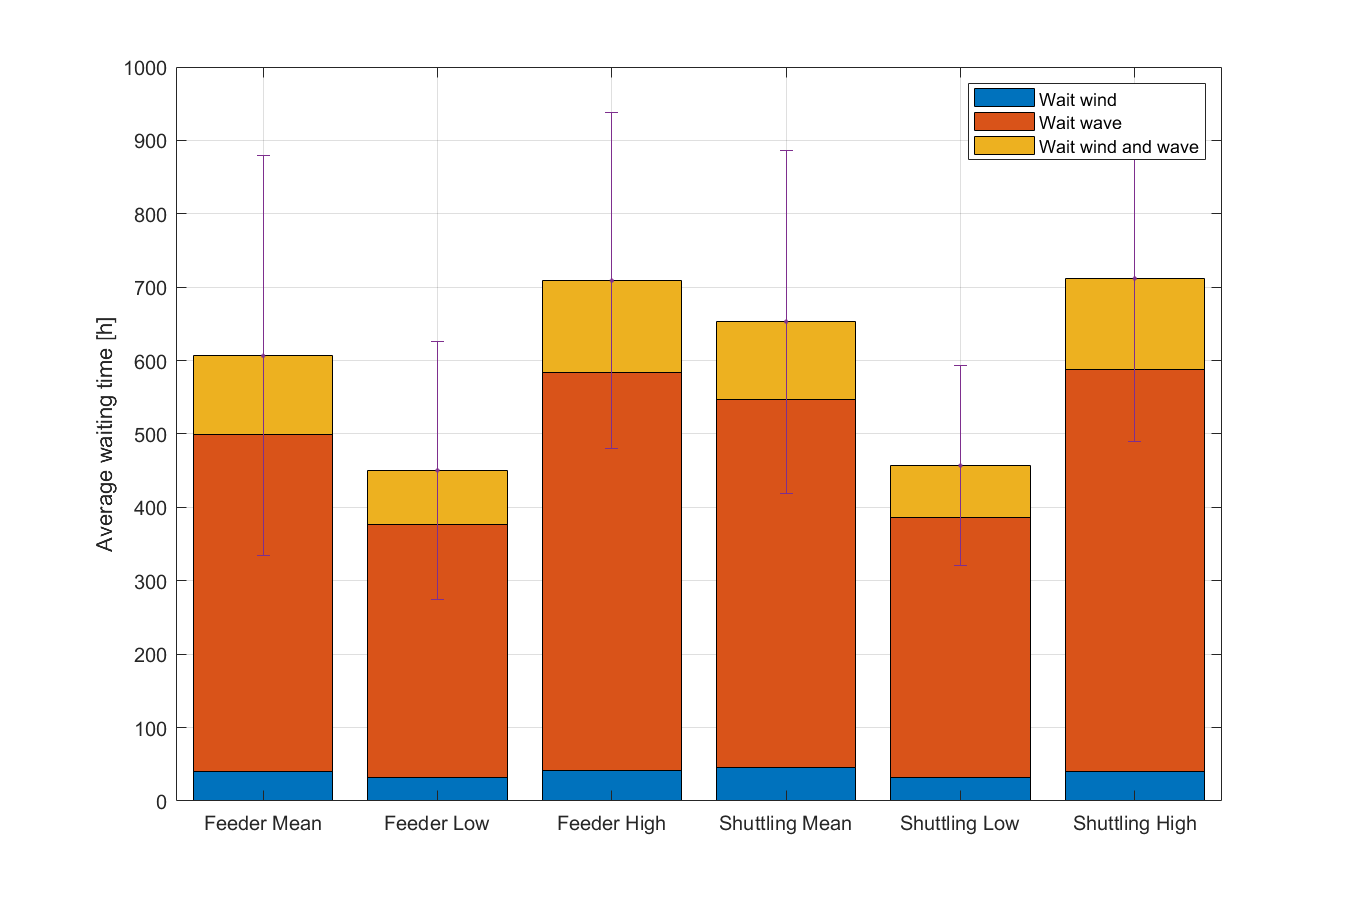

% Waiting_combined=Waiting_hs(11,:)+Waiting_tp(11,:)+Waiting_wind(11,:)+Waiting_tide(11,:);
% 
% Waitings=[WAIT_TOT(11,:);Waiting_combined]';
% figure()
% bar(x,Waitings), hold on
% ylabel('Waiting time [h]')
% grid on
% legend('Total average','Combined average')

%Waiting_stacked=[Waiting_wave(11,:);Waiting_wind(11,:);Waiting_tide(11,:)]';
Waiting_stacked=[Waiting_wind(11,:);Waiting_wave(11,:);Waiting_windwave(11,:)]';
f4=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,Waiting_stacked,'stacked'), hold on
errorbar(WAIT_TOT(11,:),std_WAIT_TOT ,'.')
ylabel('Average waiting time [h]')
grid on
%legend('Wait Wave','Wait wind','Wait tide')
legend('Wait wind','Wait wave','Wait wind and wave')
exportgraphics(f4,'WaitingTimesCond.pdf')

## Wait Op Scenarios 1 & 4

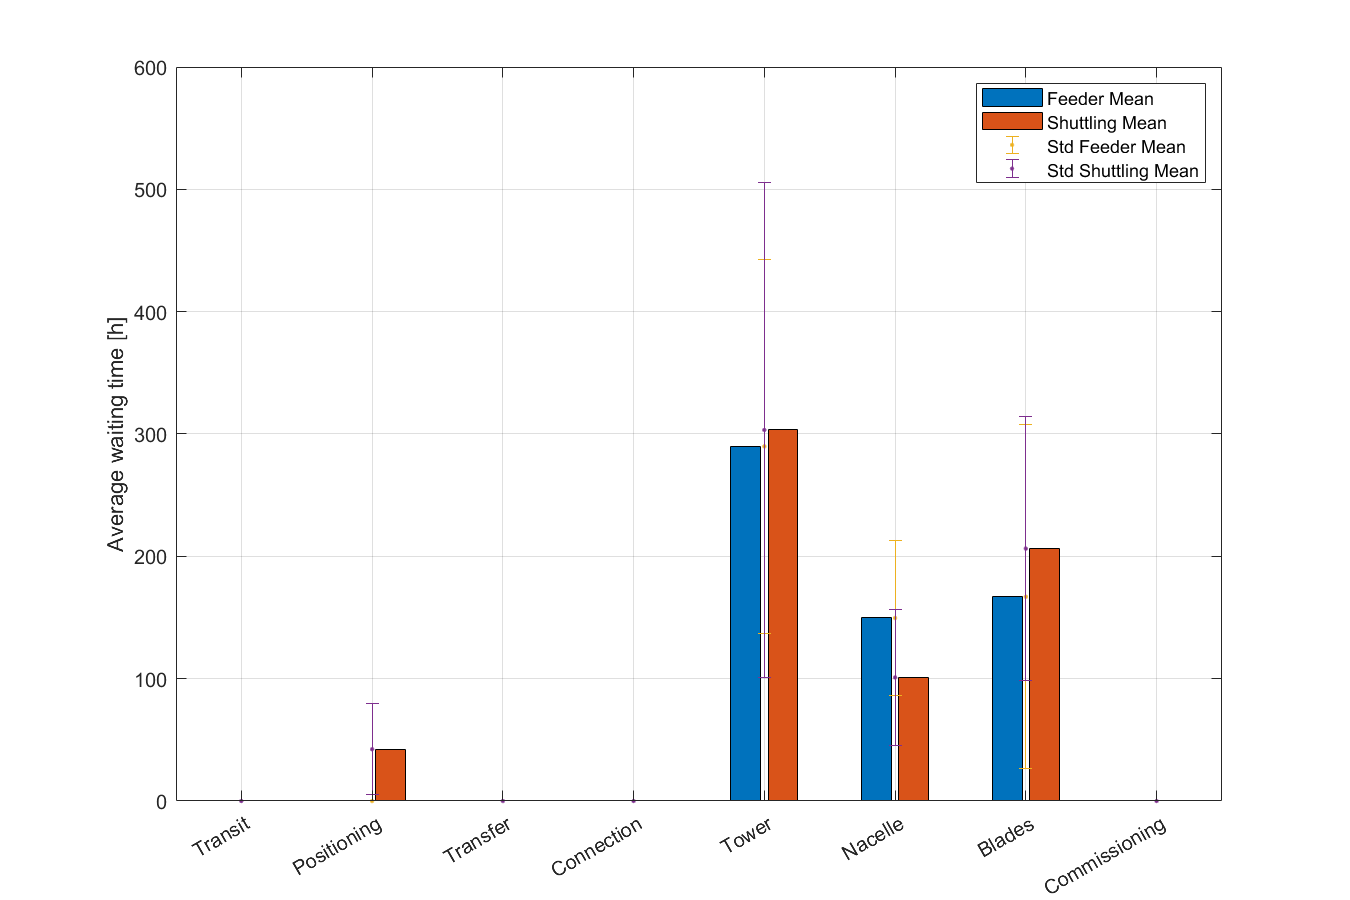

Waiting_Ops=[Waiting_transit(11,1) Waiting_transit(11,4);Waiting_position(11,1) Waiting_position(11,4);Waiting_transfer(11,1) Waiting_transfer(11,4);Waiting_connect(11,1) Waiting_connect(11,4);Waiting_tower(11,1) Waiting_tower(11,4);Waiting_nacelle(11,1) Waiting_nacelle(11,4);Waiting_blade(11,1) Waiting_blade(11,4);Waiting_commission(11,1) Waiting_commission(11,4)]';

x_alt=categorical({'Transit','Positioning','Transfer','Connection','Tower','Nacelle','Blades','Commissioning'});
x_alt = reordercats(x_alt,{'Transit','Positioning','Transfer','Connection','Tower','Nacelle','Blades','Commissioning'});

f5=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x_alt,Waiting_Ops), hold on
errorbar(Waiting_Ops(1,:),std_Ops14(1,:),'.')
errorbar(Waiting_Ops(2,:),std_Ops14(2,:),'.')
ylabel('Average waiting time [h]')
grid on
legend('Feeder Mean','Shuttling Mean','Std Feeder Mean','Std Shuttling Mean')
exportgraphics(f5,'Op14WaitTimes.pdf')

## Wait Op all Scenarios

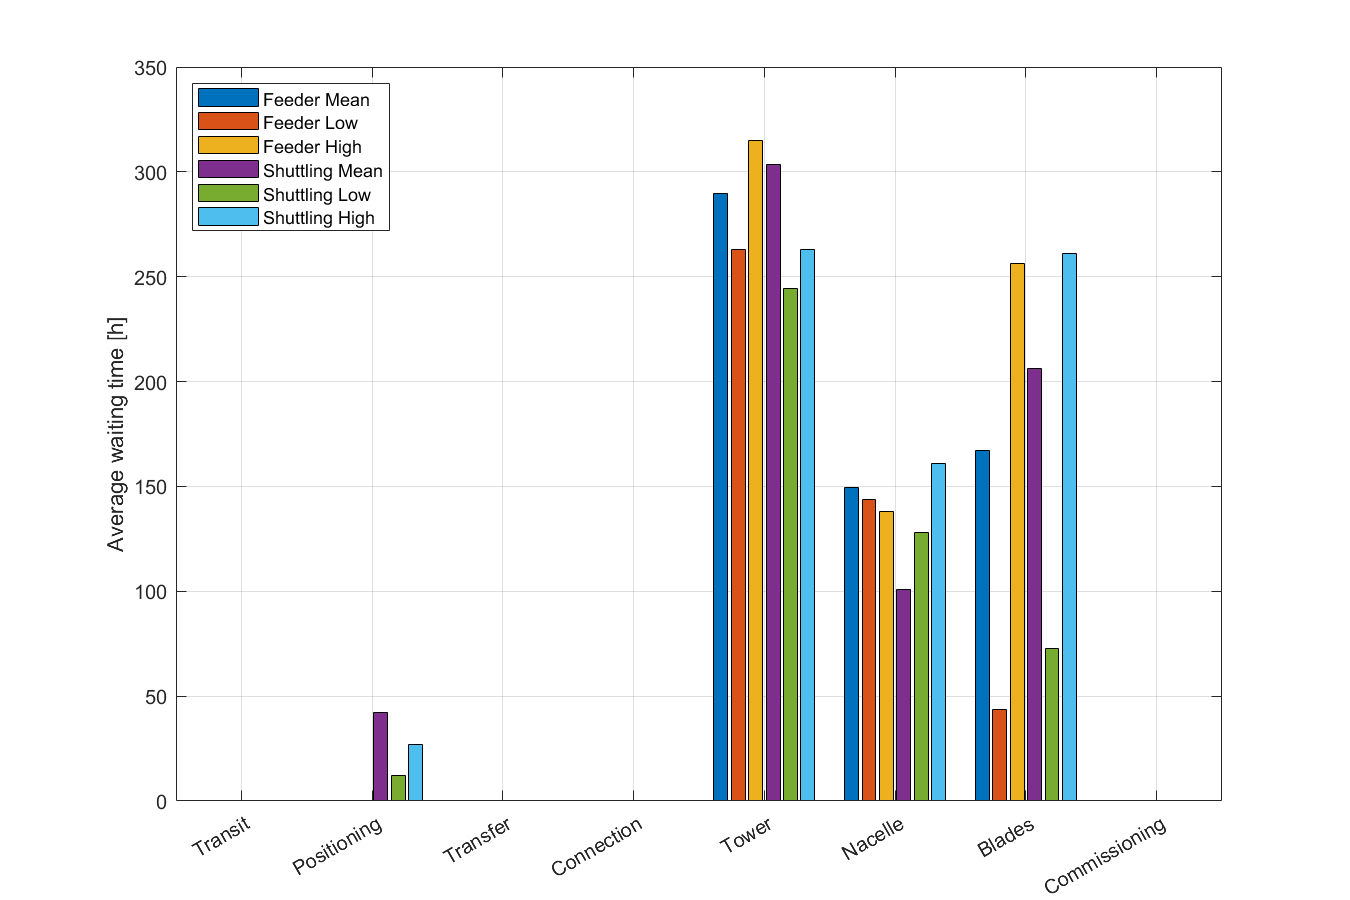

Waiting_Ops2=[Waiting_transit(11,:);Waiting_position(11,:);Waiting_transfer(11,:);Waiting_connect(11,:);Waiting_tower(11,:);Waiting_nacelle(11,:);Waiting_blade(11,:);Waiting_commission(11,:)]';

x_alt=categorical({'Transit','Positioning','Transfer','Connection','Tower','Nacelle','Blades','Commissioning'});
x_alt = reordercats(x_alt,{'Transit','Positioning','Transfer','Connection','Tower','Nacelle','Blades','Commissioning'});

f6=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x_alt,Waiting_Ops2), hold on
ylabel('Average waiting time [h]')
grid on
legend('Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High','Location','northwest')
exportgraphics(f6,'OpAllWaitTimes.pdf')

## Month comparions

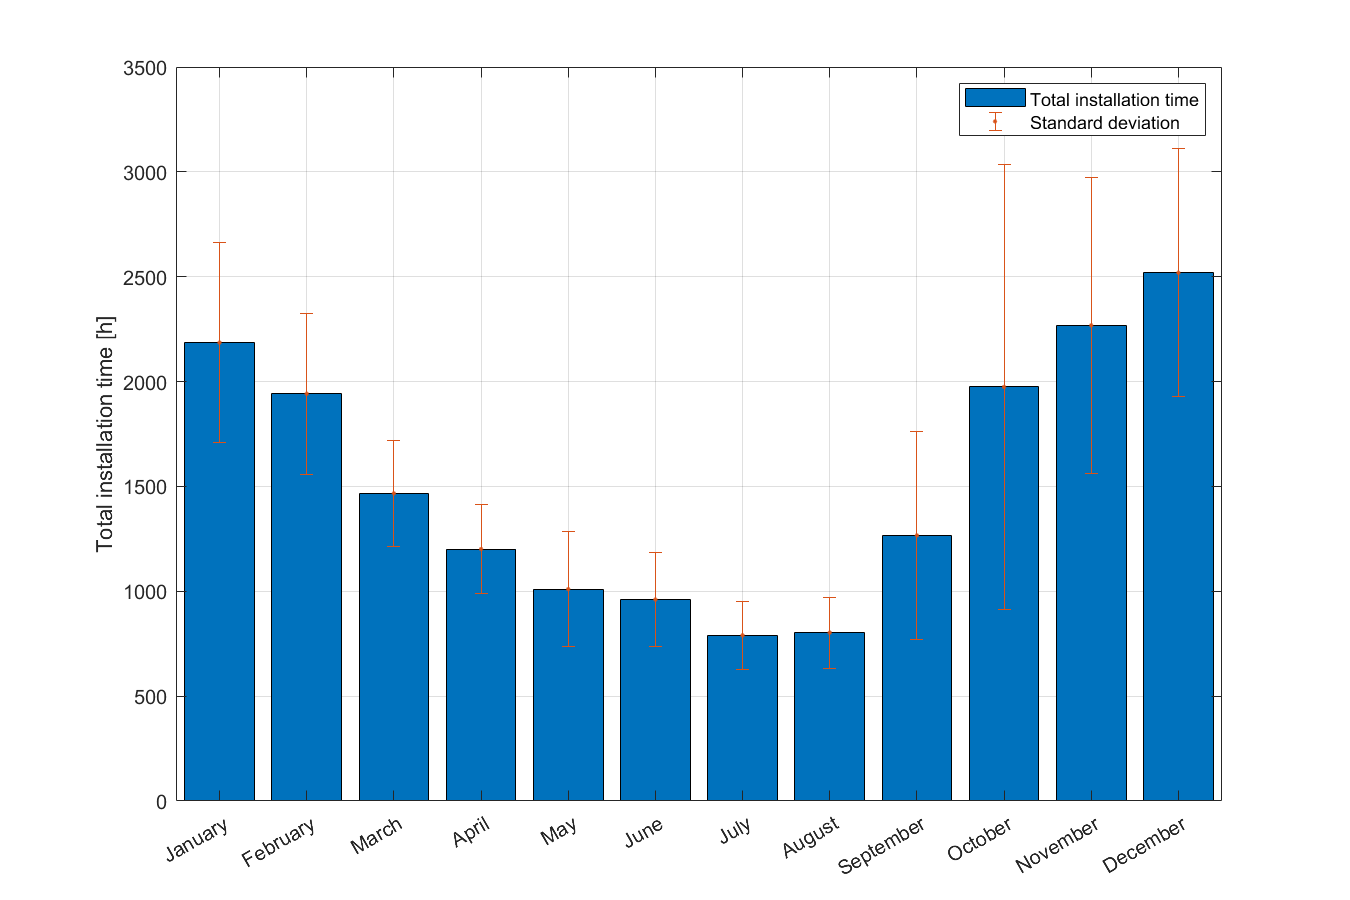

T_TOT_S1=T_TOT_CALM(1)*[1 1 1 1 1 1 1 1 1 1 1 1];
COST_TOT_S1=COST_TOT_CALM(1)*[1 1 1 1 1 1 1 1 1 1 1 1];
std_T_TOT_mo = std(T_TOT_mo(1:10,:), 1);
std_COST_TOT_mo = std(COST_TOT_mo(1:10,:), 1);

mo=categorical({'January','February','March','April','May','June','July','August','September','October','November','December'});
mo = reordercats(mo,{'January','February','March','April','May','June','July','August','September','October','November','December'});
% 
% T_TOT_mo_comp=[T_TOT_S1; T_TOT_mo(11,:)-T_TOT_S1]';
% figure()
% bar(mo,T_TOT_mo_comp,'stacked'), hold on
% errorbar(T_TOT_mo(11,:),std_T_TOT_mo ,'.')
% ylabel('Total installation time [h]')
% grid on
% legend('Calm weather','Operational limits')

% 
% COST_TOT_mo_comp=[COST_TOT_S1/1000; (COST_TOT_mo(11,:)-COST_TOT_S1)/1000]';
% figure()
% bar(mo,COST_TOT_mo_comp,'stacked'), hold on
% errorbar(COST_TOT_mo(11,:)/1000,std_COST_TOT_mo/1000 ,'.')
% ylabel('Total installation cost [m€]')
% grid on
% legend('Calm weather','Operational limits')



Ratios_mo=T_TOT_mo(11,:);
std_T_TOT_Ratio = std_T_TOT_mo;
f7=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(mo,T_TOT_mo(11,:)'), hold on
ylabel('Total installation time [h]')
errorbar(T_TOT_mo(11,:)',std_T_TOT_mo' ,'.')
grid on
legend('Total installation time','Standard deviation')
exportgraphics(f7,'MonthlyInstTime.pdf')

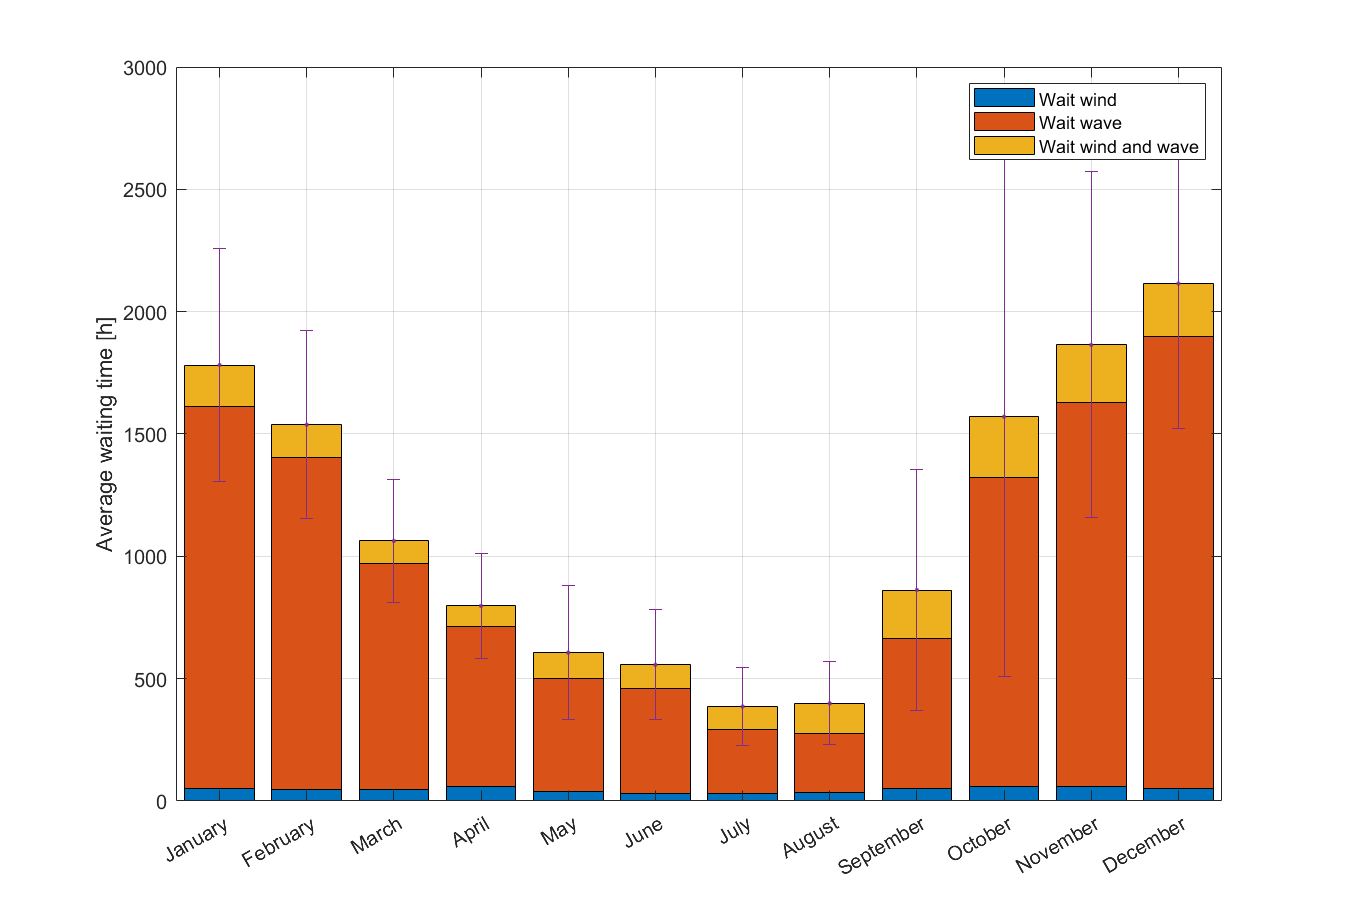



std_WAIT_TOT_mo = std(WAIT_TOT_mo(1:10,:), 1);


%Waiting_stacked_mo=[Waiting_wave_mo(11,:);Waiting_wind_mo(11,:);Waiting_tide_mo(11,:)]';
Waiting_stacked_mo=[Waiting_wind_mo(11,:);Waiting_wave_mo(11,:);Waiting_windwave_mo(11,:)]';
f8=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(mo,Waiting_stacked_mo,'stacked'), hold on
errorbar(WAIT_TOT_mo(11,:),std_WAIT_TOT_mo ,'.')
ylabel('Average waiting time [h]')
grid on
%legend('Wait Wave','Wait wind','Wait tide')
legend('Wait wind','Wait wave','Wait wind and wave')
exportgraphics(f8,'MonthlyWaitTime.pdf')

## Scenario plots comp low

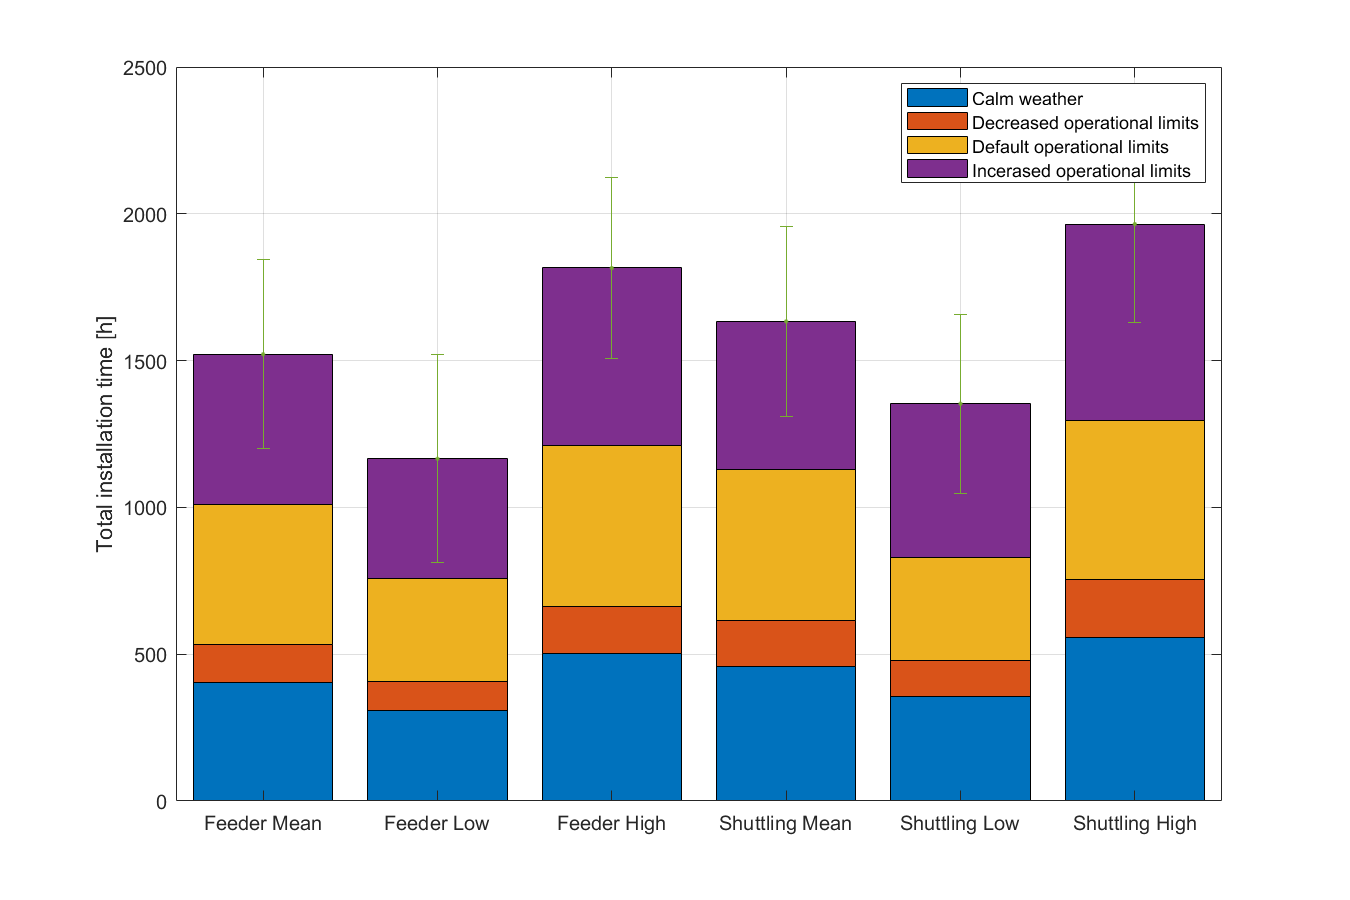


x=categorical({'Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High'});
x = reordercats(x,{'Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High'});
T_TOT_bars_lo=[T_TOT_CALM; T_TOT_hi(11,:)-T_TOT_CALM;  T_TOT(11,:)-T_TOT_hi(11,:);T_TOT_lo(11,:)-T_TOT(11,:)]';
f9=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,T_TOT_bars_lo,'stacked'), hold on
errorbar(T_TOT_lo(11,:),std_T_TOT_lo ,'.')
ylabel('Total installation time [h]')
grid on
legend('Calm weather','Decreased operational limits','Default operational limits','Incerased operational limits')

exportgraphics(f9,'TotInstTimeIncLim.pdf')

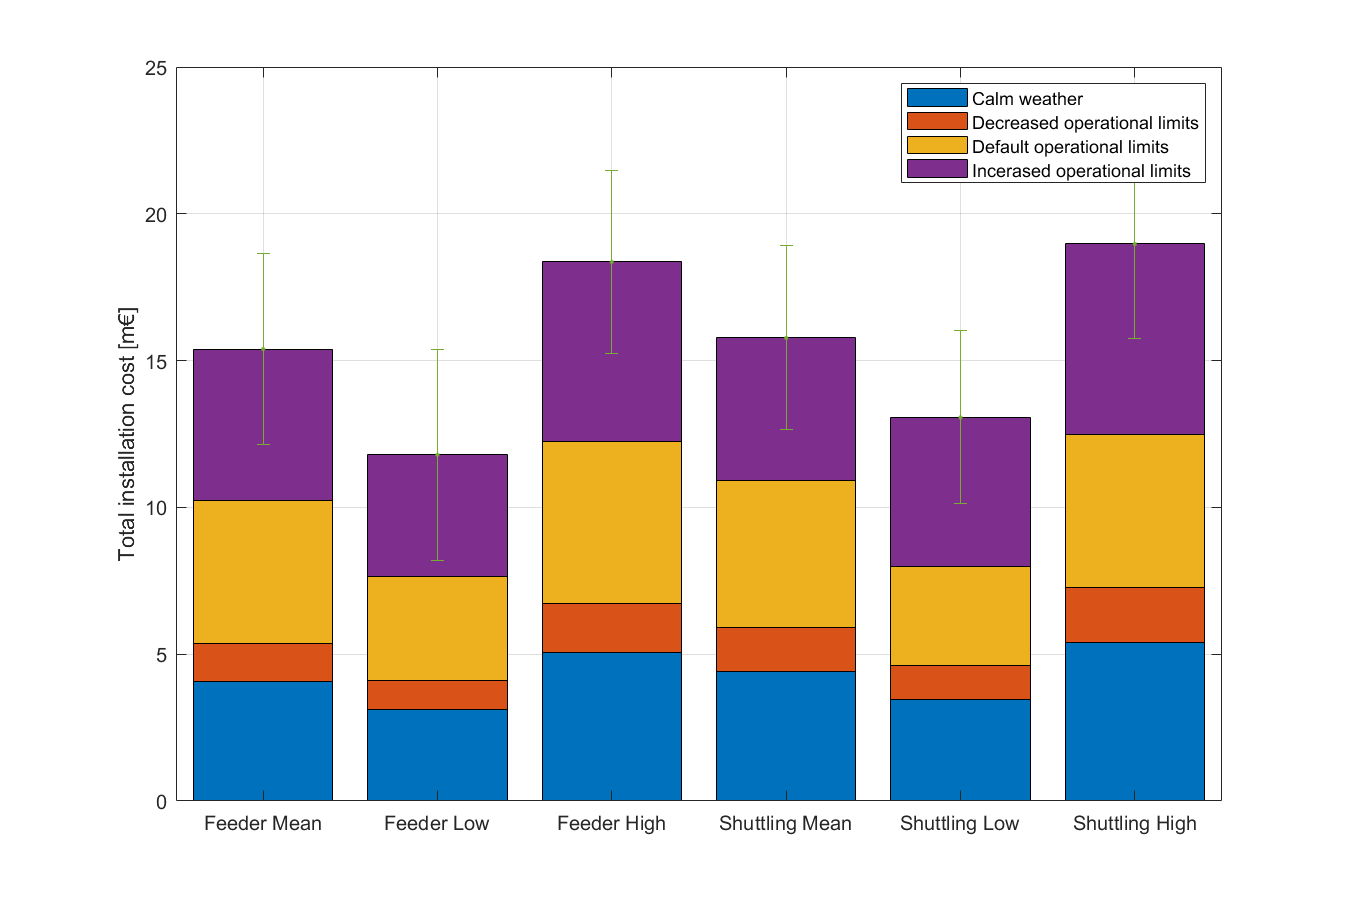



COST_TOT_bars_lo=[COST_TOT_CALM/1000; (COST_TOT_hi(11,:)-COST_TOT_CALM)/1000;(COST_TOT(11,:)-COST_TOT_hi(11,:))/1000; (COST_TOT_lo(11,:)-COST_TOT(11,:))/1000]';
f10=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,COST_TOT_bars_lo,'stacked'), hold on
errorbar(COST_TOT_lo(11,:)/1000,std_COST_TOT_lo/1000 ,'.')
ylabel('Total installation cost [m€]')
grid on
legend('Calm weather','Decreased operational limits','Default operational limits','Incerased operational limits')
exportgraphics(f10,'TotInstCostIncLim.pdf')

## Ratio plots

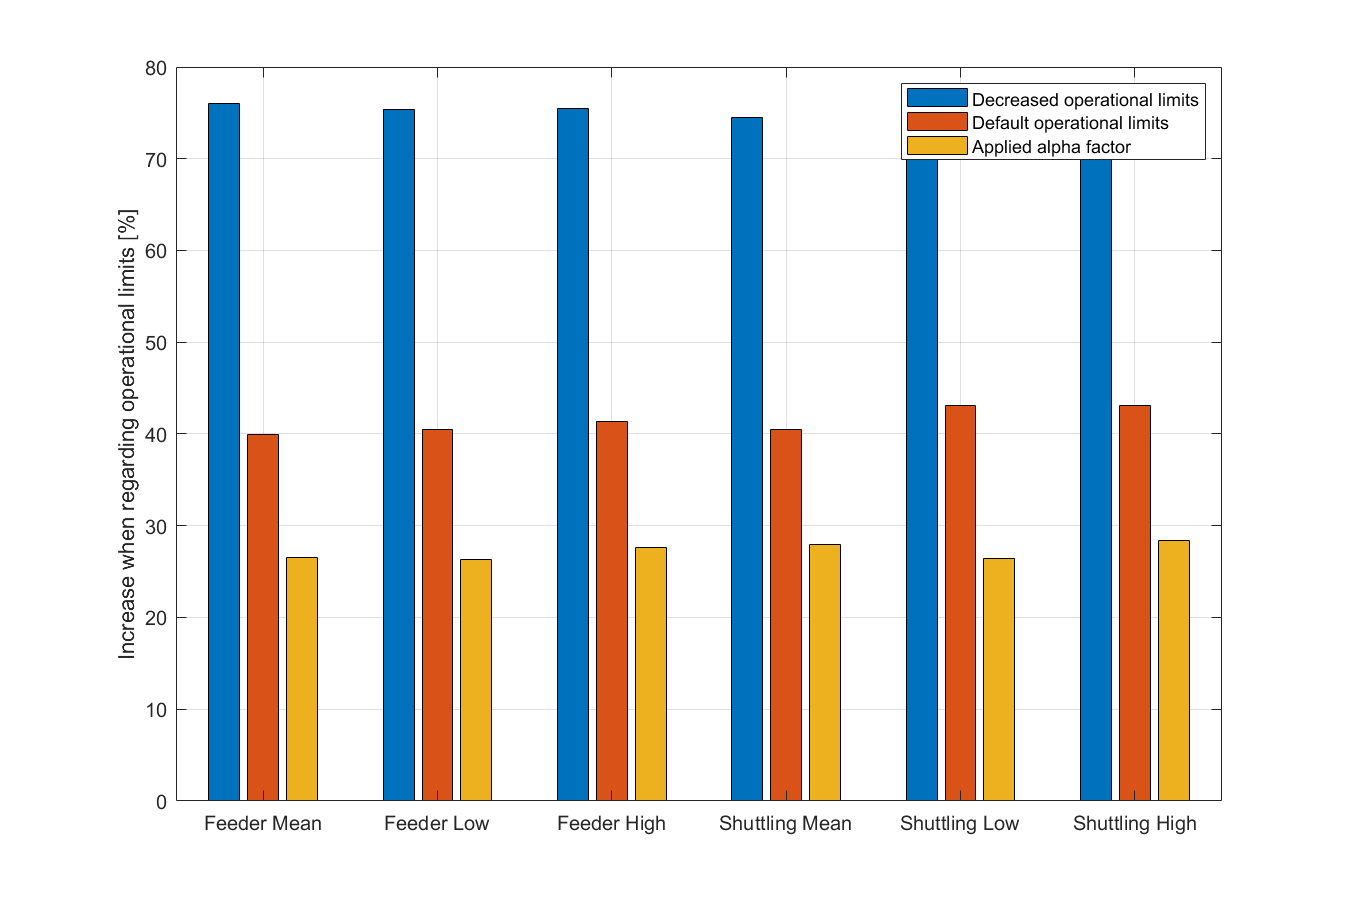

Ratios_lo=[((T_TOT_CALM./T_TOT_hi(11,:)))*100;((T_TOT_CALM./T_TOT(11,:)))*100;((T_TOT_CALM./T_TOT_lo(11,:)))*100]';
f11=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,Ratios_lo), hold on
ylabel('Increase when regarding operational limits [%]')
grid on
legend('Decreased operational limits','Default operational limits','Applied alpha factor')
exportgraphics(f11,'OperabilityScenarios.pdf')

## Waiting plots

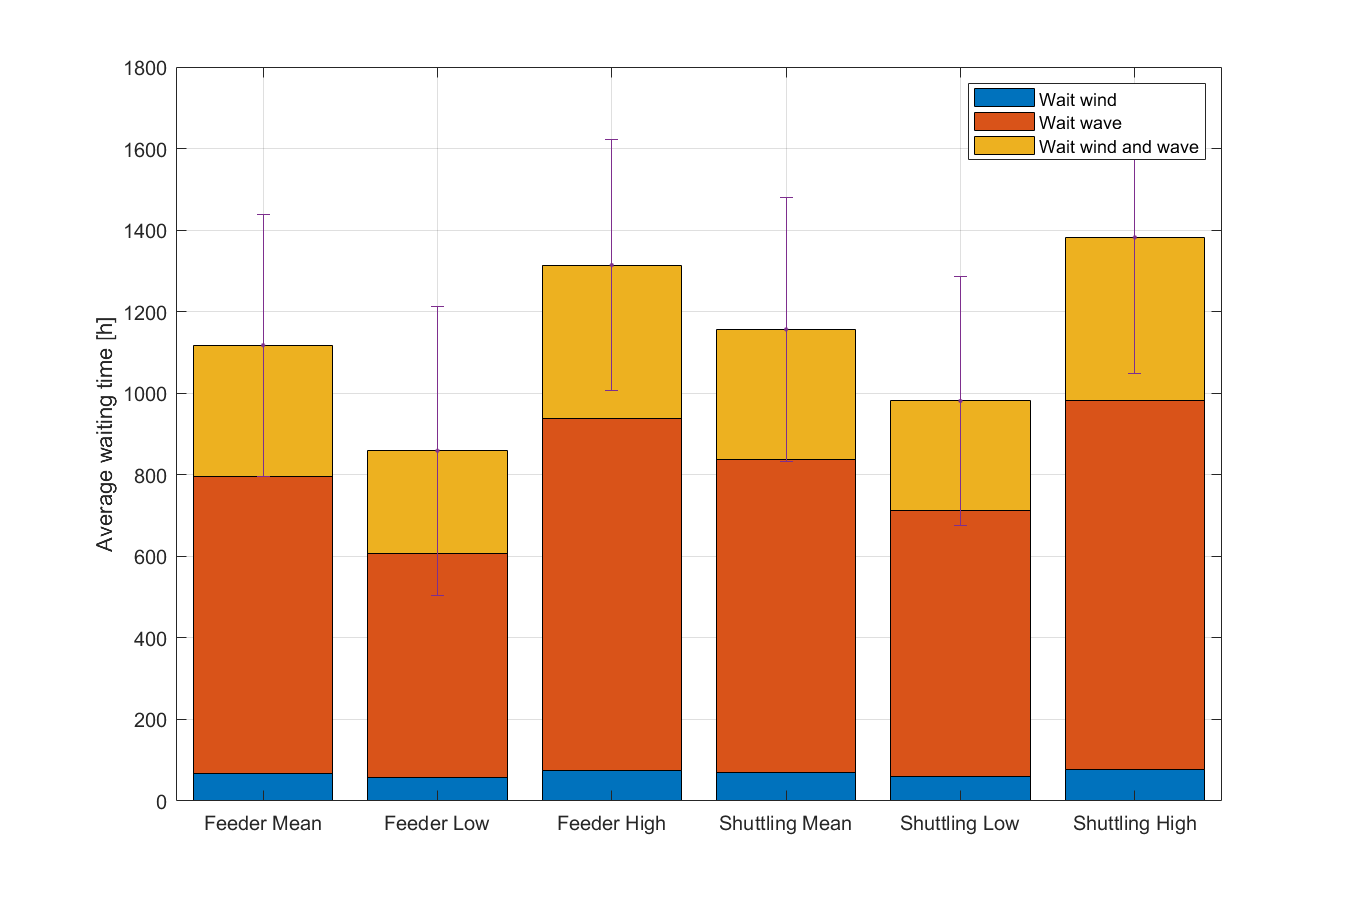

% Waiting_combined=Waiting_hs(11,:)+Waiting_tp(11,:)+Waiting_wind(11,:)+Waiting_tide(11,:);
% 
% Waitings=[WAIT_TOT(11,:);Waiting_combined]';
% figure()
% bar(x,Waitings), hold on
% ylabel('Waiting time [h]')
% grid on
% legend('Total average','Combined average')

%Waiting_stacked_lo=[Waiting_wave_lo(11,:);Waiting_wind_lo(11,:);Waiting_tide_lo(11,:)]';
Waiting_stacked_lo=[Waiting_wind_lo(11,:);Waiting_wave_lo(11,:);Waiting_windwave_lo(11,:)]';
f12=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,Waiting_stacked_lo,'stacked'), hold on
errorbar(WAIT_TOT_lo(11,:),std_WAIT_TOT_lo ,'.')
ylabel('Average waiting time [h]')
grid on
%legend('Wait Wave','Wait wind','Wait tide')

legend('Wait wind','Wait wave','Wait wind and wave')
exportgraphics(f12,'WaitingTimesCondIncLim.pdf')

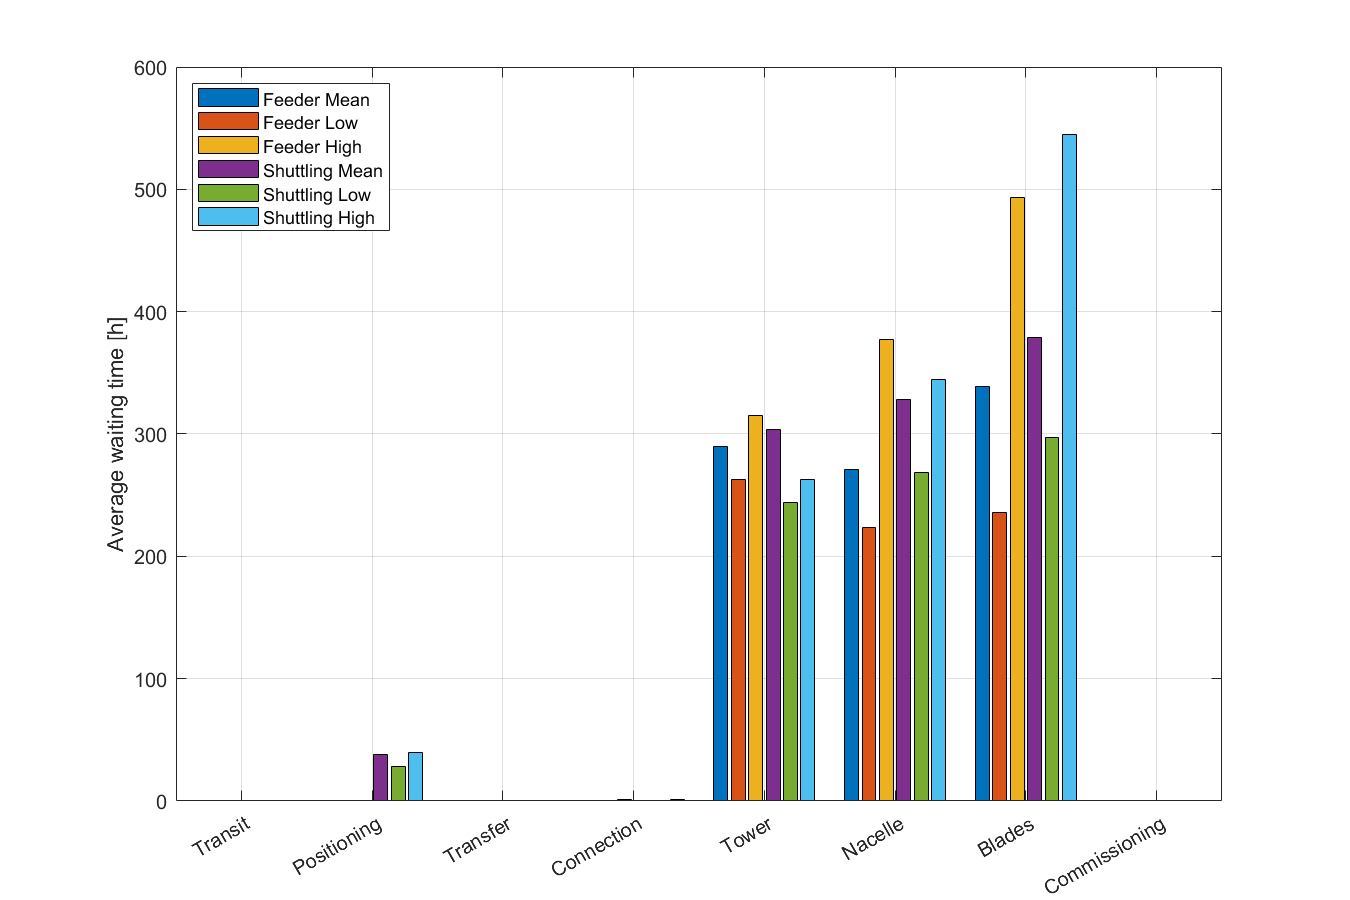


Waiting_Ops2_lo=[Waiting_transit_lo(11,:);Waiting_position_lo(11,:);Waiting_transfer_lo(11,:);Waiting_connect_lo(11,:);Waiting_tower(11,:);Waiting_nacelle_lo(11,:);Waiting_blade_lo(11,:);Waiting_commission_lo(11,:)]';

x_alt=categorical({'Transit','Positioning','Transfer','Connection','Tower','Nacelle','Blades','Commissioning'});
x_alt = reordercats(x_alt,{'Transit','Positioning','Transfer','Connection','Tower','Nacelle','Blades','Commissioning'});

f6=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x_alt,Waiting_Ops2_lo), hold on
ylabel('Average waiting time [h]')
grid on
legend('Feeder Mean','Feeder Low','Feeder High','Shuttling Mean','Shuttling Low','Shuttling High','Location','northwest')

%exportgraphics(f6,'OpAllWaitTimes.pdf')

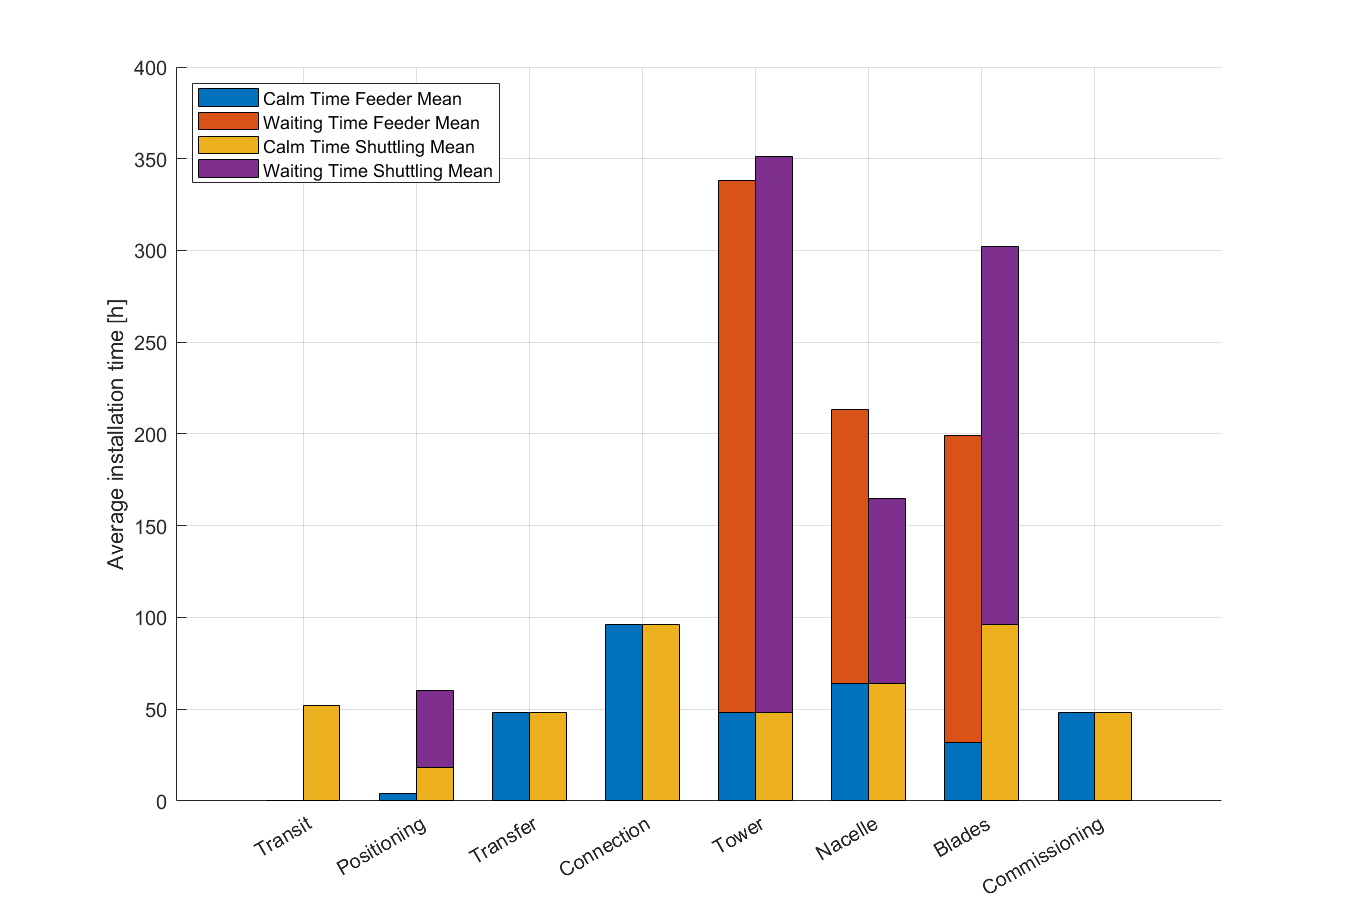


Sheet1=[T_TRANS_TOT_CALM(1) T_TRANS_TOT_CALM(4);T_POS_TOT_CALM(1) T_POS_TOT_CALM(4);T_LOAD_TOT_CALM(1) T_LOAD_TOT_CALM(4);T_CON_TOT_CALM(1) T_CON_TOT_CALM(4);T_TOW_TOT_CALM(1) T_TOW_TOT_CALM(4);T_NAC_TOT_CALM(1) T_NAC_TOT_CALM(4);T_BLADE_TOT_CALM(1) T_BLADE_TOT_CALM(4);T_COM_TOT_CALM(1) T_COM_TOT_CALM(1)];
Sheet2=[Waiting_transit(11,1) Waiting_transit(11,4);Waiting_position(11,1) Waiting_position(11,4);Waiting_transfer(11,1) Waiting_transfer(11,4);Waiting_connect(11,1) Waiting_connect(11,4);Waiting_tower(11,1) Waiting_tower(11,4);Waiting_nacelle(11,1) Waiting_nacelle(11,4); Waiting_blade(11,1) Waiting_blade(11,4);Waiting_commission(11,1) Waiting_commission(11,4)];

Sheet1(:,:,2)=Sheet2;
stackData=Sheet1;
% labels to use on tick marks for groups
groupLabels = {'Transit', 'Positioning', 'Transfer', 'Connection', 'Tower', 'Nacelle', 'Blades', 'Commissioning'};
f15=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plotBarStackGroups(stackData, groupLabels);
grid on
ylabel('Average installation time [h]')
legend('Calm Time Feeder Mean','Waiting Time Feeder Mean','Calm Time Shuttling Mean','Waiting Time Shuttling Mean','Location','northwest')
exportgraphics(f15,'OpTimes.pdf')

## Size comparisons

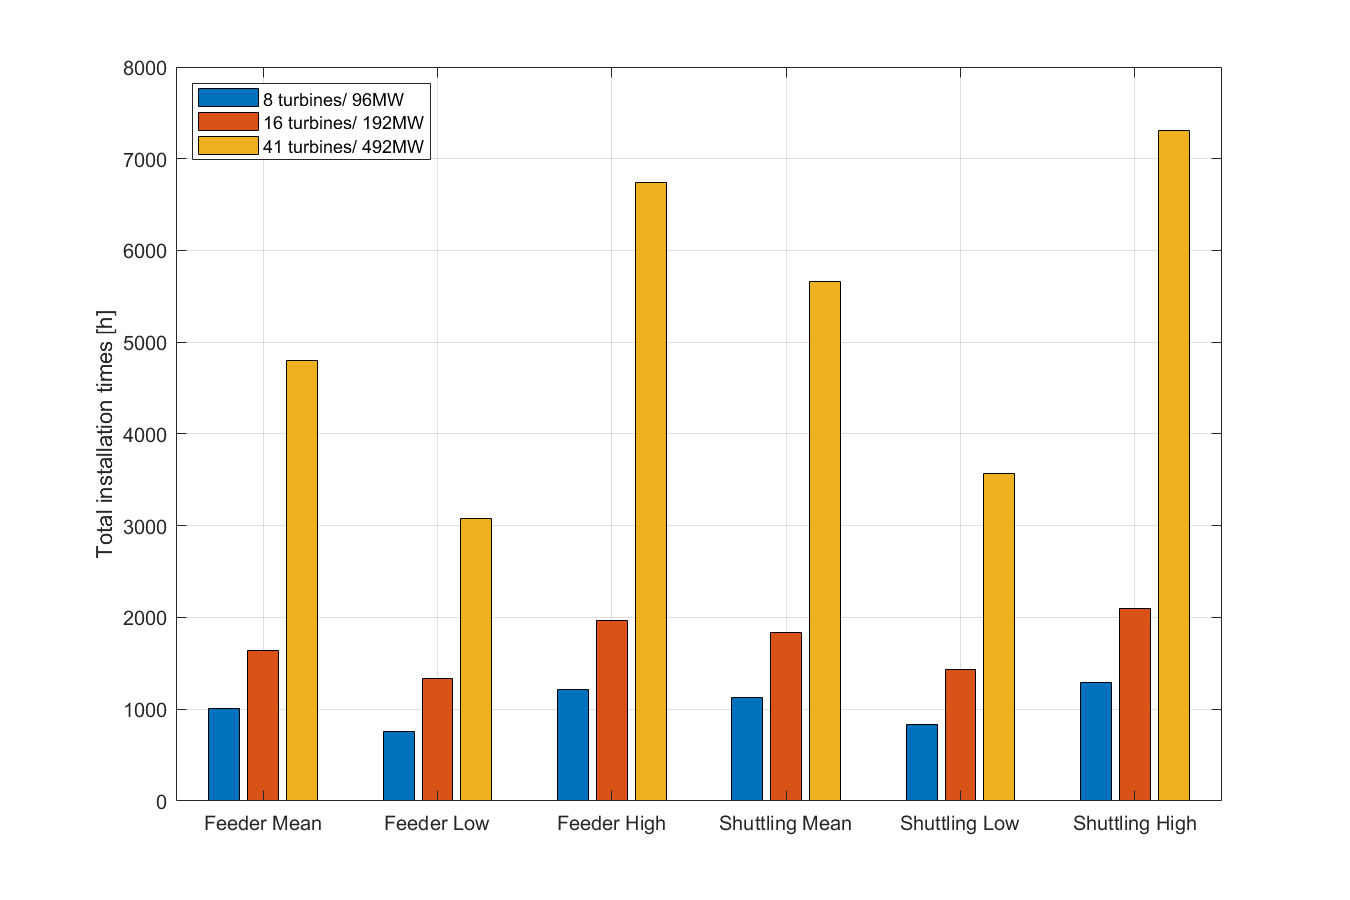

InstTimes=[T_TOT(11,:);T_TOT_200(11,:);T_TOT_500(11,:)]';
f500=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,InstTimes), hold on
ylabel('Total installation times [h]')
grid on
legend('8 turbines/ 96MW','16 turbines/ 192MW','41 turbines/ 492MW','Location','northwest')
exportgraphics(f500,'ScaleUpTime.pdf')

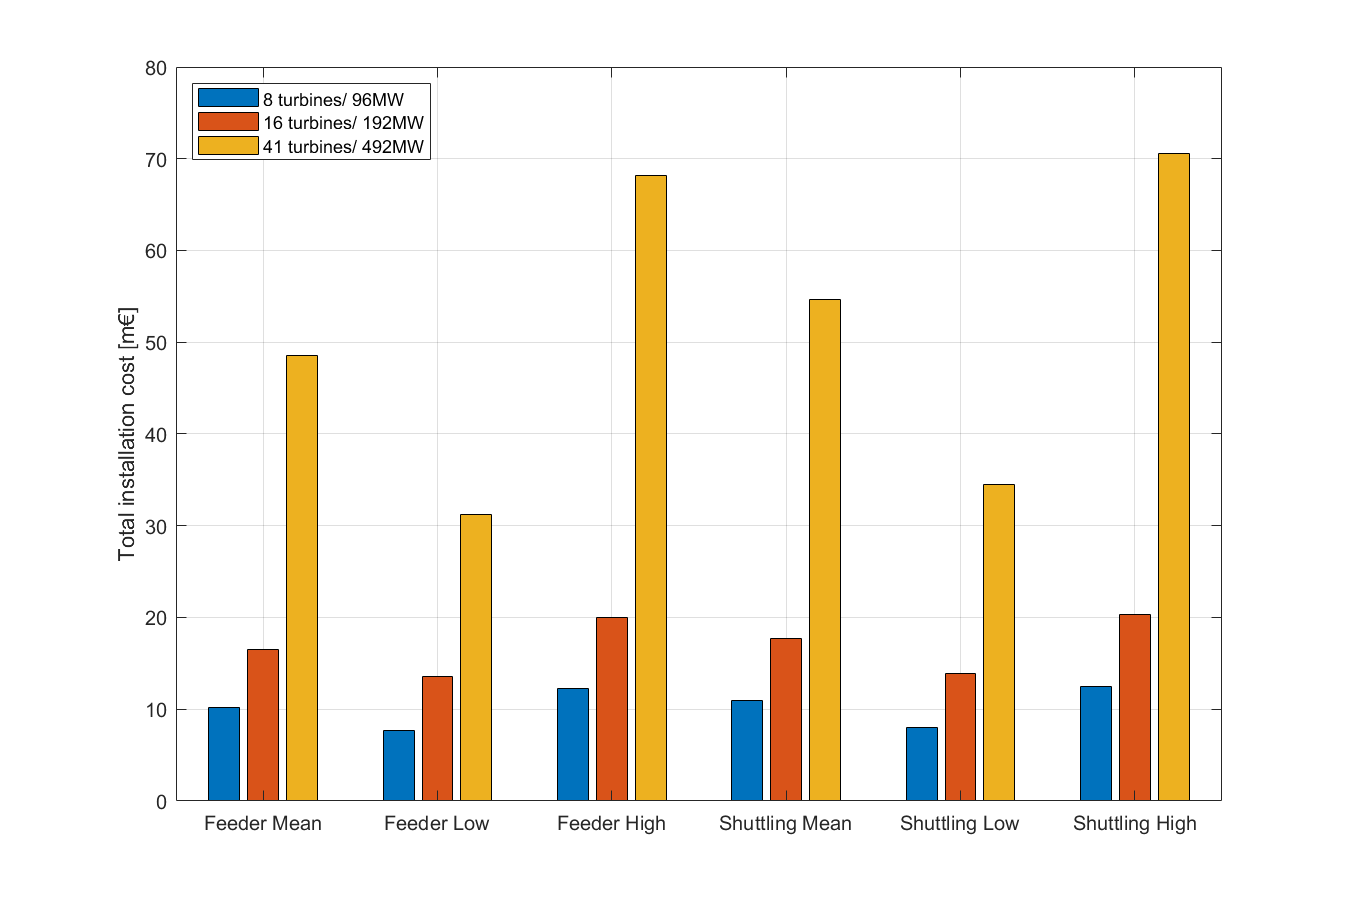


InstTimes=[COST_TOT(11,:)/1000;COST_TOT_200(11,:)/1000;COST_TOT_500(11,:)/1000]';
f501=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,InstTimes), hold on
ylabel('Total installation cost [m€]')
grid on
legend('8 turbines/ 96MW','16 turbines/ 192MW','41 turbines/ 492MW','Location','northwest')
exportgraphics(f501,'ScaleUpCost.pdf')

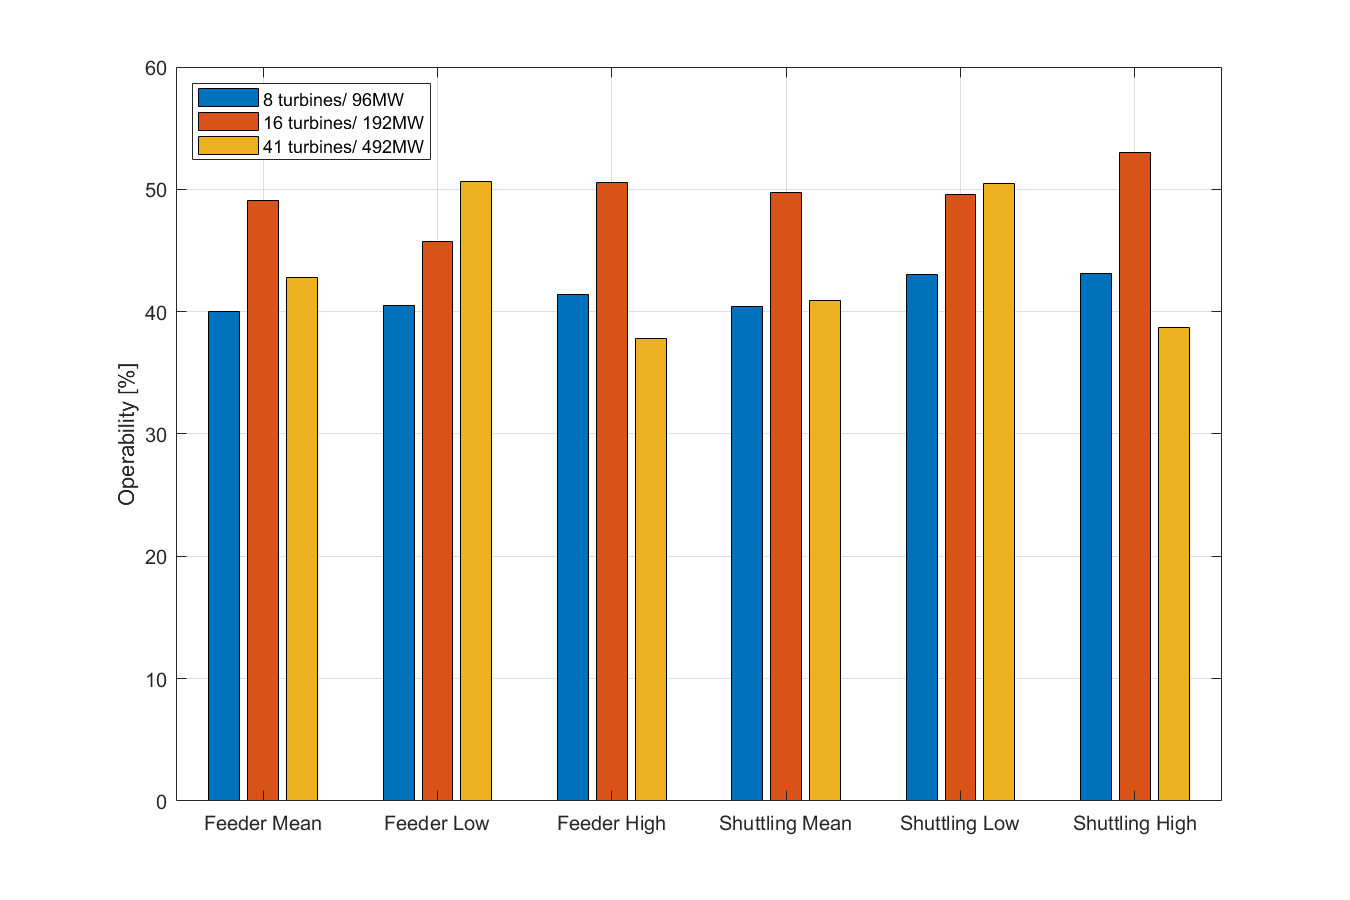


OpScale=[((T_TOT_CALM./T_TOT(11,:)))*100;((T_TOT_CALM_200./T_TOT_200(11,:)))*100;((T_TOT_CALM_500./T_TOT_500(11,:)))*100]';
f502=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
bar(x,OpScale), hold on
ylabel('Operability [%]')
grid on
legend('8 turbines/ 96MW','16 turbines/ 192MW','41 turbines/ 492MW','Location','northwest')
exportgraphics(f502,'OperabilityScale.pdf')